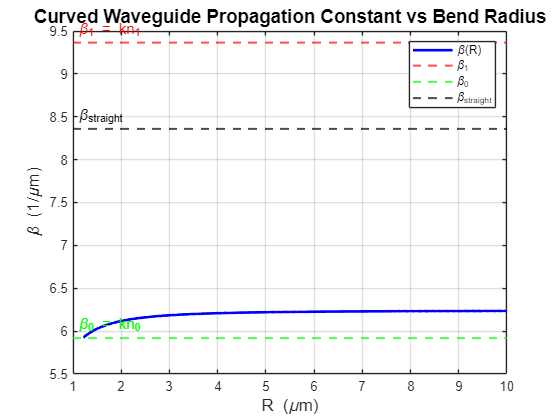

clear; clc; close all;

% Parameters
lambda = 1.55e-6;
a      = 0.225e-6;
n1     = 2.31;
n0     = 1.46;
k      = 2*pi/lambda;
beta1  = k*n1;   % wavenumber in core
beta0  = k*n0;   % wavenumber in cladding

%solve straight waveguide for initial beta guess
V = k*a*sqrt(n1^2 - n0^2);
disp_eq = @(b) V*sqrt(1-b) - atan(sqrt(b/(1-b)));
b0      = fzero(disp_eq, [0.001, 0.999]);
beta_straight = k*sqrt(n0^2 + b0*(n1^2 - n0^2));

function val = disp_curved(beta, R, a, n1, n0, k)
    v  = beta * R;
    Rm = R - a;   % R-
    Rp = R + a;   % R+

    % Bessel arguments
    x0m = n0*k*Rm;    % n0*k*R-
    x1m = n1*k*Rm;    % n1*k*R-
    x1p = n1*k*Rp;    % n1*k*R+
    x0p = n0*k*Rp;    % n0*k*R+

    % Bessel values
    Jv_x0m = besselj(v, x0m);
    Jv_x1m = besselj(v, x1m);   Yv_x1m = bessely(v, x1m);
    Jv_x1p = besselj(v, x1p);   Yv_x1p = bessely(v, x1p);
    % Hankel function of second kind: H^(2) = J - iY
    Hv_x0p = besselj(v, x0p) - 1j*bessely(v, x0p);

    % Derivatives via recurrence: B'_v(x) = -B_{v+1}(x) + (v/x)*B_v(x)
    Jd_x0m = -besselj(v+1,x0m) + (v/x0m)*Jv_x0m;
    Jd_x1m = -besselj(v+1,x1m) + (v/x1m)*Jv_x1m;
    Yd_x1m = -bessely(v+1,x1m) + (v/x1m)*Yv_x1m;
    Jd_x1p = -besselj(v+1,x1p) + (v/x1p)*Jv_x1p;
    Yd_x1p = -bessely(v+1,x1p) + (v/x1p)*Yv_x1p;
    Hd_x0p = -( besselj(v+1,x0p) - 1j*bessely(v+1,x0p) ) + (v/x0p)*Hv_x0p;

    % 4x4 matrix from notes
    M = [ Jd_x0m,        -Jd_x1m,        -Yd_x1m,              0;
          0,              Jd_x1p,          Yd_x1p,       Hd_x0p;
         -n0*Jd_x0m,     -n1*Jd_x1m,     -n1*Yd_x1m,           0;
          0,              n1*Jd_x1p,       n1*Yd_x1p,   -n0*Hd_x0p];

    val = det(M);
end

%sweep R and solve for beta
R_vec    = linspace(1e-6, 10e-6, 500);
beta_vec = zeros(size(R_vec));
beta_guess = beta_straight;

for i = 1:length(R_vec)
    R = R_vec(i);
    f = @(beta) real(disp_curved(beta, R, a, n1, n0, k));
    try
        % Narrow bracket around expected zero crossing
        beta_vec(i) = fzero(f, [beta0*1.001, beta_straight*0.999]);
        beta_guess  = beta_vec(i);
    catch
        beta_vec(i) = NaN;
    end
end

% Convert to 1/um for readability
R_um    = R_vec * 1e6;
beta_um = beta_vec * 1e-6;

%plot
figure;
plot(R_um, beta_um, 'b-', 'LineWidth', 2);
hold on;

% Reference lines
yline(beta1*1e-6, 'r--', '\beta_1 = kn_1', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'FontSize', 11);
yline(beta0*1e-6, 'g--', '\beta_0 = kn_0', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'FontSize', 11);
yline(beta_straight*1e-6, 'k--', '\beta_{straight}',  'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'FontSize', 11);

xlabel('R (\mum)', 'FontSize', 13);
ylabel('\beta (1/\mum)', 'FontSize', 13);
title('Curved Waveguide Propagation Constant vs Bend Radius', 'FontSize', 14);
xlim([1, 10]);
legend('\beta(R)', '\beta_1', '\beta_0', '\beta_{straight}', 'Location', 'best');
grid on;